# JMO Spectrum Library Documentation

Version 1.0, Sept. 13th, 2019

Julius Muschaweck, JMO GmbH, Zugspitzstr. 66, 82131 Gauting, Germany. julius@jmoptics.de

## Rationale

We deal routinely with spectra in illumination optics. We need to analyze LED spectra, compute color coordinates and color rendering values from spectra, integrate them, add spectra, multiply spectra with scalar weights and with other spectra (like transmission spectra), interpolate a given measured spectrum with non-equidistant wavelength values to a regular 1 nm array, and so on.

In practice, this is tedious: spectra come in various formats, and the problem of dealing with two spectra als tabulated values which have two different sets of wavelengths is annoying.

This open source Matlab library is designed to make these engineering tasks easy and transparent. It is compatible with GNU Octave, and with Matlab for Mac and Linux. 

## License -- public domain

I release this software into the public domain under [CC0](https://creativecommons.org/publicdomain/zero/1.0/legalcode)

## Getting started

To define a spectrum and compute its CIE xy color coordinates, simply say

clear s;
s.lam = [360 830];
s.val = [1 1];
% this is a flat spectrum, known as CIE standard illuminant E. 
% By definition, it should have color coordinates x == y == 1/3-
s.XYZ = CIE1931_XYZ(s);
% This is a common pattern: Compute information from a spectrum, and then
% add this information to the same spectrum as an additional field
s

s = struct with fields:
    lam: [360 830]
    val: [1 1]
    XYZ: [1×1 struct]


s.XYZ

ans = struct with fields:
    X: 106.8654
    Y: 106.8569
    Z: 106.8919
    x: 0.3333
    y: 0.3333
    z: 0.3334


## Design decisions

### Spectrum

In this library, a *spectrum* is a struct with at least two fields named `lam` and `val`, which meet the following requirements:

- `lam` is a 1D vector of numeric values which are not complex, > 0, and strictly ascending

- `val` is a 1D vector of numeric values which are not complex.

- `lam `and `val `are of same length and have at least two elements

It is desirable for `lam `and `val `to be column vectors.

There is a function `rv = SpectrumSanityCheck(rhs)`, which tests all these requirements and, if met, returns the same struct except that `lam `and `val `are converted to column vectors if necessary.

A *spectrum* models the function *S(lambda)* which represents a physical scalar function of wavelength. Like spectral radiant flux, spectral irradiance, spectral radiant intensity, spectral radiance, spectral transmission, spectral absorption, spectral efficiency. The tabulated values in `val `are linearly interpolated. Outside the range given by `lam`*, * *S(lambda)* == 0.

`lam `is considered to have units of nanometers in all library functions that make use of this unit, e.g. color calculations.

Why structs and not classes? Classes are nice to guarantee that properties like `lam `and `val `always are present, and would allow methods which operate directly on spectra. However, structs are simpler and more versatile. I, as the library designer, cannot know which additional information a user (I myself, for example), wants to attach to a given spectrum. Name, date, name of LED, color coordinates and more. To make a spectrum s, I can simply say

clear s
nfig = 0; %figure number to be used in examples
s.lam = [360 830];
s.val = [1 1];
s.name = "CIE standard illuminant E";
s.hopp = "topp";
s

s = struct with fields:
     lam: [360 830]
     val: [1 1]
    name: "CIE standard illuminant E"
    hopp: "topp"


to give it an appropriate name and an arbitrary value in an arbitrary additional field. Of course, a user can always create a subclass to add properties to a given class, but it is just so much simpler to assign to an additional struct field in a single line. In my experience, these conventions for spectra are simple and few enough to be easily remembered and adhered to.

### Conventions

In my code, I like to have long unabbreviated variable and function names. Except for a few standards:

`rv` is my name for the return value of a function

`spec `is my name for a single spectrum argument of a function.

`lhs `and `rhs  `are short for 'left hand side' and 'right hand side', the arguments of a binary function.

Proper library function names start with capital letters, e.g. `MakeSpectrum`. Internal helper functions start with a small "i", e.g. `iLinInterpolProto`.

A spectrum struct is valid if it has fields lam and `val `which fulfill the requirements above. In addition, I assume a spectrum may have the following fields:

`name`*: * A short character string with a name. 

`description`*: *A longer character string with a description.

`XYZ`*: * A struct with tristimulus and color coordinate fields `X, Y, Z, x, y, z`, typically created by code like `s.XYZ = CIE1931_XYZ(s)`

## Function reference

### Alphabetic list

AddSpectra adds two spectra

AddWeightedSpectra adds multiple spectra with weights

CCT_from_xy computes correlated color temperature and uv-distance to Planck locus from spectrum

CIE1931_lam_x_y_z.mat contains CIE 1931 data for color matching functions, monochromatic border and Planck locus

CIE1931_XYZ computes CIE 1931 XYZ color coordinates and tristimulus values from spectrum

CODATA2018 returns a struct with CODATA 2018 values for relevant physical constants (speed of light, Boltzmann constant etc.)

GaussSpectrum creates a Gaussian spectrum for given mean and standard deviation

IsOctave determines if running on GNU Octave or Matlab

LinInterpol computes linear interpolation like `interp1, `but about five times faster on Matlab on Windows

LinInterpolAdd4Async computes linear interpolation of the sum of four functions

MakeSpectrum creates a valid spectrum from wavelength and value data

MultiplySpectra multiplies two spectra, e.g. an LED spectrum with a transmission spectrum

PlanckLocus returns a wealth of information about the Planck locus, including interpolation function objects and Judd lines of equal CCT

PlanckSpectrum creates a blackbody spectrum with various normalizations to choose from

SpectrumSanityCheck checks if a spectrum fulfills the requirements

TestLinInterpol tests the LinInterpol function

### `AddSpectra`

Adds two spectra without weights. Convenience function with simpler interface than AddWeightedSpectra

% function rv = AddSpectra(lhs, rhs)

**Input:** `lhs, rhs`*: *Both must be valid spectra.

**Output:** `rv`*: *Sum of `rhs + lhs`. When both spectra do not overlap, the wavelength ranges are concatenated, and the range in between is padded with zero. If they do overlap, then `rv.lam` contains all values from both input spectra, with duplicate values removed, and what is added are the linearly interpolated values from both input spectra. Thus, the sum spectrum is a perfect model of the underlying continuous function which is the sum of the continuous, linearly interpolated input spectra.

Additional fields present in `lhs `or `rhs `will be stripped, `rv `will have only fields `lam `and `val.`

**Usage Example:**

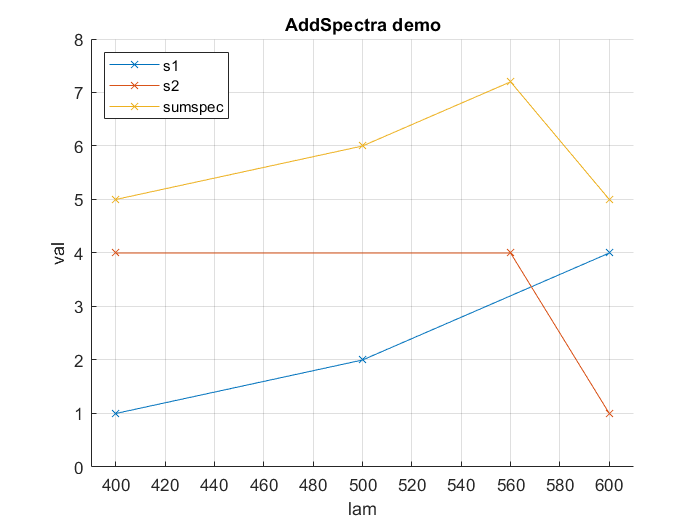

clear s1 s2 sumspec
s1 = MakeSpectrum([400,500,600],[1, 2, 4]);
s2 = MakeSpectrum([400,560,600],[4, 4, 1]);
sumspec = AddSpectra(s1,s2);
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
plot(s1.lam, s1.val,'Marker','x');
plot(s2.lam, s2.val,'Marker','x');
plot(sumspec.lam, sumspec.val,'Marker','x');
legend({'s1','s2','sumspec'},'Location','NorthWest');
axis([390 610 0 8]);
grid on;
xlabel('lam');
ylabel('val');
title('AddSpectra demo');

### `AddWeightedSpectra`

Computes weighted sum of several spectra.

% function rv = AddWeightedSpectra(spectra,weights)

**Input:**

`spectra`: Nonempty *c*ell array of spectra

`weights`*: *Vector of numeric non-complex values, same length as `spectra`*.*

**Output:** `rv`*: *Weighted sum of input spectra. When spectra do not overlap, the wavelength ranges are concatenated, and the range in between is padded with zero. If they do overlap, then `rv.lam` contains all values from all input spectra, with duplicate values removed, and sorted, and what is added are the linearly interpolated values from all input spectra. Thus, the sum spectrum is a perfect model of the function which is the sum of the continuous, linearly interpolated input spectra.

Additional fields present in `spectra` will be stripped, `rv `will have only fields `lam `and `val`*.*

**Usage Example:**

Add a red, a green, and a blue spectrum created by GaussSpectrum

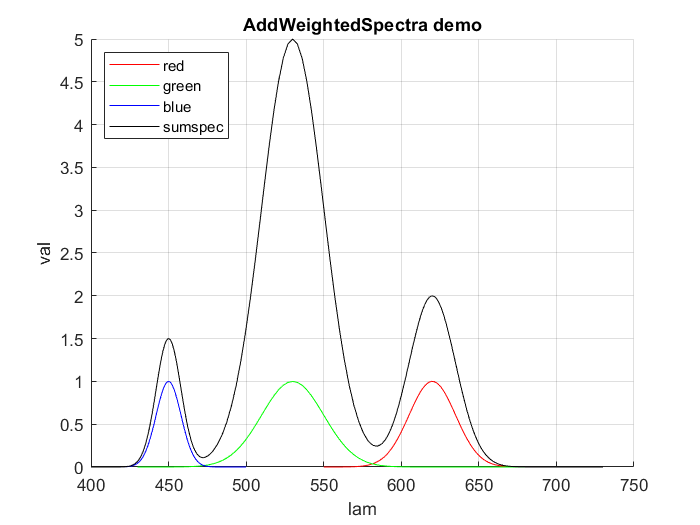

clear red green blue sumspec
red = GaussSpectrum(linspace(550,700),620,15);
green = GaussSpectrum(linspace(430,730),530,20);
blue = GaussSpectrum(linspace(400,500),450,8);
sumspec = AddWeightedSpectra({red, green, blue},[2, 5, 1.5]);
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
plot(red.lam, red.val,'r');
plot(green.lam, green.val,'g');
plot(blue.lam, blue.val,'b');
plot(sumspec.lam, sumspec.val,'k');
legend({'red','green','blue','sumspec'},'Location','NorthWest');
grid on;
xlabel('lam');
ylabel('val');
title('AddWeightedSpectra demo');

## `CCT_from_xy`

Compute correlated color temperature of an xy color point. Uses parabolic interpolation between nearest Planck locus points

% function [CCT, dist_uv] = CCT_from_xy(x,y)

**Input:** `x, y` scalar numbers, x/y color coordinates

**Output:** 

`CCT: ` Correlated color temperature in Kelvin

`dist_uv: `Distance to Planck locus in u/v color space. When `dist_uv>0.05, `a warning is issued, when `dist_uv `> 0.09, an error. Positive when x/y is above Planck locus (on the "green" side), negative when below.

**Usage Example:**

clear T pl jl uv den x y CCT dist_uv
T = 3456; 
pl = PlanckLocus;
jl = pl.JuddLine_func(T);
% compute uv coordinates for color point with CCT == T,
% 0.04 away from Planck
uv = [jl.u, jl.v] + 0.04 * [jl.du, jl.dv];
% compute xy coordinates by standard transformation 
den = 2*uv(1) - 8*uv(2) + 4;
x = 3*uv(1)/den;
y = 2 * uv(2) / den;
% compute CCT 
[CCT, dist_uv] = CCT_from_xy(x,y);
CCT - T % should be zero, is about 1.3 mK

ans = 0.0013

dist_uv - 0.04 % should be zero

ans = -4.3846e-07

## `CIE1931_lam_x_y_z.mat`

A .mat file which contains a struct named `'CIE1931XYZ' `with CIE 1931 data: x/y/z color matching functions, monochromatic border x/y coordinates with corresponding wavelengths, and coordinates of the Planck locus with corresponding absolute temperatures.

**Usage Example:**

clear CIE1931XYZ;
load('CIE1931_lam_x_y_z.mat','CIE1931XYZ')
CIE1931XYZ

CIE1931XYZ = struct with fields:
        lam: [471×1 double]
          x: [471×1 double]
          y: [471×1 double]
          z: [471×1 double]
    xBorder: [471×1 double]
    yBorder: [471×1 double]
    PlanckT: [1001×1 double]
    Planckx: [1001×1 double]
    Plancky: [1001×1 double]


### `CIE1931_XYZ`

Computes CIE 1931 color coordinates.

% function rv = CIE1931_XYZ(spec)

**Input: **`spec` is a *spectrum *struct, see above for requirements.

**Output:** A struct with fields `X Y Z x y z`. 

Capital   `X Y Z `are the CIE tristimulus values, i.e. the result of integrating `spec` with the CIE 1931 standard x y z color matching functions.

`x y z` are the corresponding color coordinates, `x = X / (X + Y + Z)`  etc.

**Usage example:**

clear s;
s.lam = [360 830];
s.val = [1 1];
% this is a flat spectrum, known as CIE standard illuminant E. 
% By definition, it should have color coordinates x == y == 1/3-
s.XYZ = CIE1931_XYZ(s);
% This is a common pattern: Compute information from a spectrum, and then
% add this information to the same spectrum as an additional field
s

s = struct with fields:
    lam: [360 830]
    val: [1 1]
    XYZ: [1×1 struct]


s.XYZ

ans = struct with fields:
    X: 106.8654
    Y: 106.8569
    Z: 106.8919
    x: 0.3333
    y: 0.3333
    z: 0.3334


## `CODATA2018`

A struct with the most relevant physical constants for optics, as defined by [CODATA](http://www.codata.org/)

% function cd = CODATA2018()

**Input:** None

**Output:** Struct with fields:

`b`: Wien's wavelength displacement law constant

`bprime`: Wien frequency displacement law constant

`c`: speed of light in vacuum

`e`: elementary charge

`h`: Planck constant

`k`: Boltzmann constant

`me`: electron mass

`mn`: neutron mass

`mp`: proton mass

`NA`: Avogadro constant

`R`: molar gas constant

`Vm`: molar volume of ideal gas

`sigma`: Stefan-Boltzmann constant

`c1`: first radiation constant (2 pi h c^2)

`c1L`: first radiation constant for spectral radiance (2 h c^2)

`c2`: second radiation constant (h c / k)

Each field is a struct with fields `name, value, reluncertainty, absuncertainty, unit. `Most uncertainties are zero, since 2018.

**Usage Example:**

clear cd lambda freq pe c
cd = CODATA2018();
lambda = 500e-9; % in meters
c = cd.c.value % speed of light

c = 299792458

freq = c/lambda% frequency of 500 nm light about 600 THz

freq = 5.9958e+14

pe = freq * cd.h.value % energy of a 500 nm photon, in Joule

pe = 3.9729e-19

## `GaussSpectrum`

Creates a normalized Gaussian spectrum with given mean and standard deviation

% function rv = GaussSpectrum(lam_vec,mean,sdev,varargin)

**Input:** 

`lam_vec: `A vector of positive reals, strictly ascending

`mean: `Scalar positive number. Mean value of the distribution. May or may not be in the `lam_vec `range.

`sdev: `Scalar positive number. Standard deviation

`varargin: `Optional string argument '`val_only'.`

**Output:** 

`rv: `Spectrum struct, with additional `name `field. Except if optional argument '`val_only`' is present: Then, rv is a column vector of the values.

**Usage Example:**

see also example for `AddWeightedSpectra.`

GaussSpectrum(400:500,450,10)

ans = struct with fields:
     val: [101×1 double]
     lam: [101×1 double]
    name: 'Gauss spectrum for mean 450 nm and sdev 10 nm, normalized to peak = 1'


## `IsOctave`

Determines if code is running under GNU Octave (or Matlab)

% function rv = IsOctave()

**Output:** Returns logical 1 when running under GNU Octave, else returns logical 0

**Usage Example:**

IsOctave()

ans = logical
   0


## `LinInterpol`

Computes linearly interpolated values of scalar tabulated function. Very similar to built in `interp1`, but uses faster C++ DLL under Matlab (on my machine, a factor of five faster).

Used internally as a helper function for higher level library functions, but exposed as a proper library function because it may well be useful to speed up computation in another context.

% function yq = LinInterpol(xx,yy,xq)

**Input:** 

`xx` is a 1D vector of numeric values which are not complex, and strictly ascending

`yy` is a 1D vector of numeric values which are not complex.

`xx` and `yy `are of same length and have at least two elements

`xq` is a 1D vector of numeric values which are not complex, and strictly ascending (the latter is NOT a requirement for `interp1`)

These preconditions are not checked.

**Output:**

`yq` is a vector of same length as `xq`*,* with linearly interpolated values. Zero if outside the `xx` range. 

**Usage Example:**

LinInterpol([1 2],[3 4],[-100,1,2,1.7])

ans =          0    3.0000    4.0000    3.7000


## `LinInterpolAdd4Async`

Computes linearly interpolated values of the sum of four input functions. Uses C++ DLL with multithreading under Matlab. On my machine, a factor of five faster than summing the result of `interp1 `calls, but not faster than summing the results of four `LinInterpol `calls. I still leave the function in place, there may be a difference for other input values and/or on another machine.

% function yq = LinInterpolAdd4Async(xx0,yy0,xx1,yy1,xx2,yy2,xx3,yy3,xq)

**Input:** 

`xx0 `is a 1D vector of numeric values which are not complex, and strictly ascending

`yy0 `is a 1D vector of numeric values which are not complex.

`xx0 `and `yy0 `are of same length and have at least two elements.

Same applies to the `xx1/yy1, xx2/yy2, xx3/yy3` pairs, but the `xx_ `arrays may all be different.

`xq `is a 1D vector of numeric values which are not complex, and strictly ascending (the latter is NOT a requirement for `interp1`!!)

**Output: **`yq` is a vector of same length as `xq`*,* with the sum of the four linearly interpolated values.

**Usage Example:**

LinInterpolAdd4Async([0 1],[1 1.1], [0 1],[2 2], [0 1],[3 3], [0 2],[4 4], [0, 1, 0.5])

ans =    10.0000   10.1000   10.0500


## `MakeSpectrum`

Creates a spectrum struct out of arrays `lam `and `val `and checks if they meet the requirements

% function rv = MakeSpectrum(lam, val)

**Input:** 

`lam `is a 1D vector of numeric values which are not complex, > 0, and strictly ascending

`val `is a 1D vector of numeric values which are not complex.

`lam `and `val `are of same length and have at least two elements.

The requirements are checked, an error thrown if violated

**Output:** 

`rv `is a spectrum struct with column vector fields `lam `and `val`*.*

**Usage Example:**

clear s
s = MakeSpectrum([400 700], [1 1])

s = struct with fields:
    lam: [2×1 double]
    val: [2×1 double]


## `MultiplySpectra`

Multiply two spectra, e.g. an LED spectrum with a transmission spectrum

% function rv = MultiplySpectra(lhs, rhs)

**Input:** `lhs, rhs: ` Valid spectrum structs. May or may not overlap.

**Output:** `rv: `Spectrum struct, modeling the product of *lhs(lambda) * rhs(lambda)*. The `rv.lam` field covers the overlap region, if any, where it contains all wavelengths from both inputs. The `rv.val `field contains the product of the respective interpolated values. There is no need to have zero values outside the overlap range, as zero is always assumed outside anyway. When there is no overlap, `rv` contains a single interval as the overall min/max wavelength range, with zero value.

**Usage Example:**

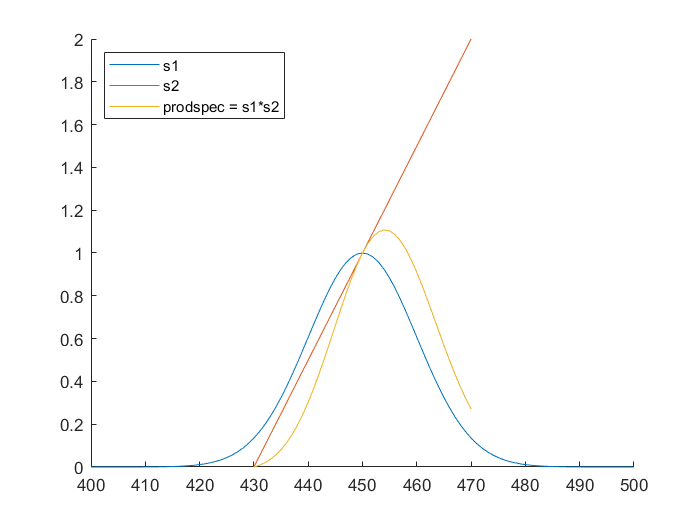

clear s1 s2 prodspec;
s1 = GaussSpectrum(400:500, 450,10);
s2 = MakeSpectrum([430 470],[0 2]);
prodspec = MultiplySpectra(s1, s2);
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
plot(s1.lam, s1.val);
plot(s2.lam, s2.val);
plot(prodspec.lam, prodspec.val);
legend({'s1','s2','prodspec = s1*s2'},'Location','northwest');

## `PlanckLocus`

Compute the x/y, u/v, u'/v' coordinates of the Planck locus, as well as interpolation function objects for x/y, u/v, and the Judd lines (lines of equal correlated color temperature) in u/v.

% function rv = PlanckLocus()

**Input:** None

**Output:** Struct with fields:

`nT`: Number of temperature points (1001)

`invT`: Inverse absolute temperature values, from near zero (1e-11) to 0.002 (1/K), in equidistant steps. (The Planck locus points are approximately equidistant in 1/T, and not at all equidistant in T)

`T`: Absolute temperature values, from 1e11 K down to 500 K

`x`: CIE 1931 x color coordinate values of the Planck locus curve

y: CIE 1931 y color coordinate values of the Planck locus curve

u: CIE u color coordinate values of the Planck locus curve (to be used only for CCT computation purposes)

v: CIE v color coordinate values of the Planck locus curve (to be used only for CCT computation purposes)

up: CIE u' (u_prime) color coordinate values of the Planck locus curve 

vp: CIE v' (v_prime) color coordinate values of the Planck locus curve 

`xy_func`: A function object to compute interpolated values of the x/y color coordinates of the Planck locus. To be called like `xy = rv.xy_func(T) `where T is a scalar of vector of absolute temperatures, and returns an array of size `[2, length(T)] `with the interpolated x values as first column and the interpolated y values as second column. Returns `NaN `when `T` is out of range 500 .. 1e11

`uv_func`: Same as `xy_func`, except it returns u/v values.

`JuddLine_func`: A function object to compute interpolated values of the Judd line parameters. To be called like `jl = rv.JuddLine_func(T) `where T is a scalar, absolute temperature. Returns a struct with fields `u, v, du, dv `where [`u,v]` are the u/v coordinates of the Planck locus point for `T`, and `[du,dv] `is the Judd line direction, normalized to length 1. By definition, the Judd line is perpendicular to the Planck locus in u/v color space, and all color points on a Judd line are deemed to have same CCT (correlated color temperature). Note that the "allowed" meaningful range is +/- 0.05 u/v length units away from the Planck locus.

**Usage Example:**

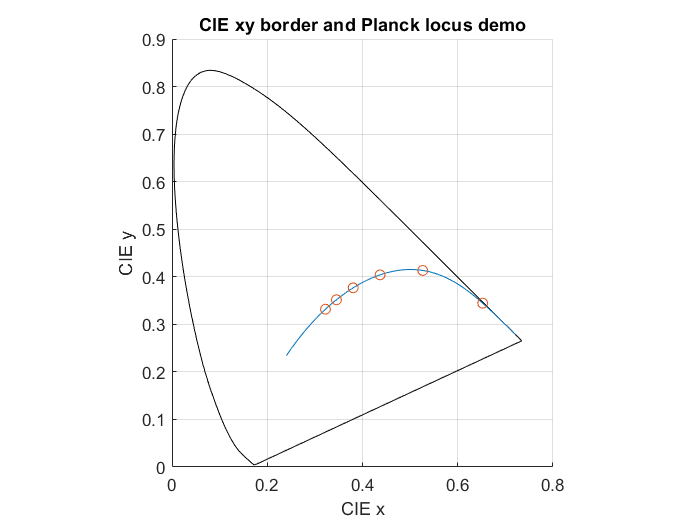

clear pl xb yb T xy
pl = PlanckLocus();
load('CIE1931_lam_x_y_z.mat','CIE1931XYZ');
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
xb = CIE1931XYZ.xBorder;
yb = CIE1931XYZ.yBorder;
xb(end+1)=xb(1); % close loop
yb(end+1)=yb(1);
plot(xb,yb,'k');
plot(pl.x,pl.y);
T = [1000 2000 3000 4000 5000 6000];
xy = pl.xy_func(T);
scatter(xy(:,1),xy(:,2));
axis equal;
grid on;
axis([0 0.8 0 0.9]);
xlabel('CIE x');
ylabel('CIE y');
title('CIE xy border and Planck locus demo')

## `PlanckSpectrum`

Generate blackbody spectrum for some absolute temperature.

% function rv = PlanckSpectrum(lam_vec, T, varargin)

**Input:** 

`lam_vec: `A wavelength vector, numeric, non-complex, positive, strictly ascending

`T: `Scalar real number, absolute temperature in K. May be `inf`, then returns `lam_vec.^(-4), `scaled to `localpeak1` (this is the high temperature limit of the shape of the long wavelength tail).

`varargin: `Name/Value pairs.

`    'normalize'` -> string, default `'globalpeak1'. `Allowed values:

`        'globalpeak1'`: scaled such that global peak would be 1.0 even if outside lambda range

`        'localpeak1'`: scaled such that the peak value is 1.0 for the given `lam_vec.` Not exactly identical if global peak is in range, due to discretization

`        'localflux1'`: scaled such that integral over `lam_vec` is 1.0

`        'radiance'`: scaled such `rv` is blackbody spectral radiance, W/(wlu m²sr). wlu is wavelengthUnit, see below

`        'exitance'`: scaled such that rv is blackbody spectral exitance, W/(wlu m²). wlu is wavelengthUnit, see belo

`    'wavelengthUnit'` -> positive real, wavelength unit in meters, default 1e-9 (nanometers). 

`        1e-9 `: `lam_vec `given in nm, returned spectrum is W / (nm m² sr) or W / (nm m²) for radiance/exitance scaling. `rv.XYZ` will be CIE XYZ values X, Y, Z, x, y

**Output:** Spectrum struct with fields

`lam: `Same as `lam_vec,` but column vector.

`val: `The spectral values, column vector of same length, normalized according to `'normalize'` (default: global peak 1.0).

`name:` string, an appropriate name

**Usage Example:**

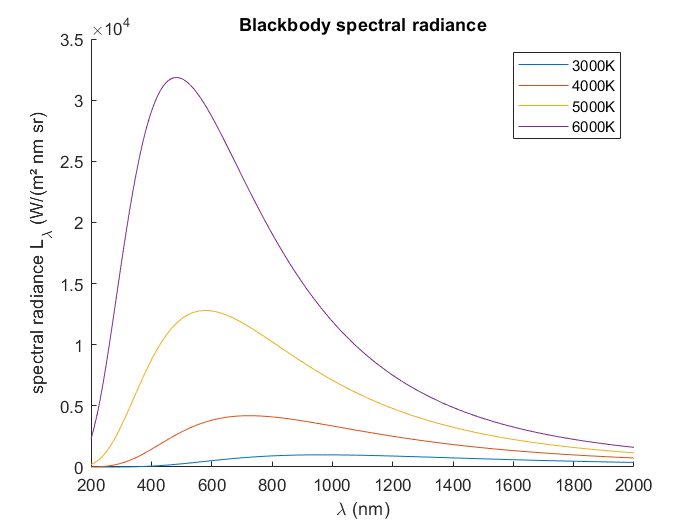

clear bb T 
nfig = nfig + 1;
figure(nfig);
clf;
hold on;
for T = [3000 4000 5000 6000]
    bb = PlanckSpectrum(200:2000,T,'normalize','radiance');
    plot(bb.lam,bb.val);
end
xlabel('\lambda (nm)');
ylabel('spectral radiance L_\lambda (W/(m² nm sr)')
legend({'3000K','4000K','5000K','6000K'})
title('Blackbody spectral radiance')

## `SpectrumSanityCheck`

Checks requirements for a spectrum variable, and returns a sanitized version of the variable, with column vectors `lam` and `val`.

% function [ok, msg, rv] = SpectrumSanityCheck(spec, varargin)

**Input:** 

`spec`  is a spectrum which should adhere to the requirements above.

`varargin `are optional name/value pairs:

    '`doThrow`', logical, default: true. If there is an error: If flag is true, throws error exception, else returns false in `ok` and an error message in *msg*.

    '`doStrip`', logical, default: false: If true returns `rv` with only the `lam` and `val` fields, else returns `rv` with all fields of input `spec`

**Output:** 

`ok`: Logical. True if there are no requirement violations, else false

`msg`*: *Character string. Empty string if there are no requirement violations, else diagnostic message.

`rv`*: *A spectrum struct where `lam` and `val `are same as in `spec `except that both are always column vectors. When the `doStrip `flag is false, also has all other fields of `spec`*. *At requirement violation, is empty array.

**Usage Example:**

clear good bad ok1 msg1 rv1 ok2 msg2 rv2
good = MakeSpectrum([400 700], [1 1]);
[ok1, msg1, rv1] = SpectrumSanityCheck(good)

ok1 = logical
   1



msg1 =

     []



rv1 = struct with fields:
    lam: [2×1 double]
    val: [2×1 double]


bad = struct('lam', [1, 2, 1], 'val', [0 0 0]);
[ok2, msg2, rv2] = SpectrumSanityCheck(bad, 'doThrow', false)

ok2 = logical
   0


msg2 = 'lam must be strictly ascending'


rv2 =

     []



## `TestLinInterpol`

A script to test the `LinInterpol` and `LinInterpolAdd4Async` functions, also measuring run times.

**Input:** none

**Output:** diagnostic text

**Usage Example:**

TestLinInterpol

LinInterpol elapsed time:3.8385e-05
interp1 elapsed time: 0.00021416, diffnorm = 0
LinInterpolAdd4Async elapsed time: 0.00011751
4 x LinInterpol elapsed time: 0.00011388, diffnorm = 0
4 x interp1 elapsed time: 0.00053468, diffnorm = 0


## `template for copy paste`

descr

% 

**Input:** x

**Output:** x

**Usage Example:**